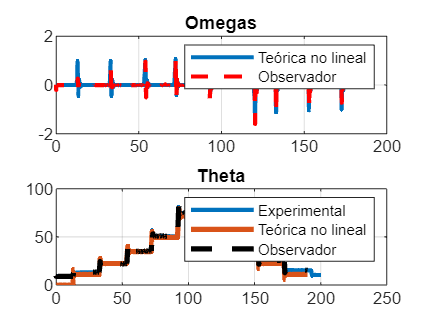

clear; close all; clc; 
addpath("data/");

load("DatosStepsVariables.mat"); 
theta_0 = 89;  % inicial
[sys, ~, ~, ~] = FoundTF(theta_0); 
load("data/TF.mat"); 

% Variables de estado 
A = sys.A; 
B = sys.B; 
C = sys.C; 
D = sys.D; 

% Matrices de ponderacion 
qx1 = 100; 
qx2 = 1000000; 
r = 1; 

Q = [qx1 0  ;0 qx2];
R = r; 

% Diseño de lqr 
[L, S, P] = lqr(A', C', Q, R); 
L = L'; 

save('LObservador.mat',"L");

addpath("sims/");
data = sim("sims/observer", 190); % Simulacion 

t = data.tout; 
% Velocities
omega = data.omega.Data ; 
omega_hat = data.omega_hat.Data; 

% Angles 
theta = data.theta.Data ; 
theta_hat = data.theta_hat.Data ; 
theta_exp = data.theta_exp.Data; 

subplot(2, 1, 1); 
plot(t, omega, t, omega_hat, "r--", "LineWidth", 2); 
title("Omegas")
legend("Teórica no lineal", "Observador"); 
grid on; 

subplot(2, 1, 2); 
plot(DatosStepsVariables(:,1), DatosStepsVariables(:,3), "LineWidth", 2); 

hold on; 
plot(t, theta, t, theta_hat, "k--", "LineWidth", 2.5); 
hold off; 

title("Theta")
legend("Experimental", "Teórica no lineal", "Observador" ); 
grid on; 

## Implementación Arduino

L

L =    42.6055
  857.6136


s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



integrador =  1/s;
intDiscrete = c2d(integrador,2.5e-3,'tustin')

intDiscrete =
 
  0.00125 z + 0.00125
  -------------------
         z - 1
 
Sample time: 0.0025 seconds
Discrete-time transfer function.




sys

sys =
 
  A = 
            theta    omega
   theta        0        1
   omega  -0.8957   -3.334
 
  B = 
              u1
   theta       0
   omega  0.9745
 
  C = 
          theta  omega
   theta      1      0
 
  D = 
          u1
   theta   0
 
Continuous-time state-space model.

